Entropy Method

load ReluPareto.mat
IPF=paretofront(:,1);
SEA=-1*paretofront(:,2);

Normalize decision matrix

normIPF=IPF/sum(IPF);
normSEA=SEA/sum(SEA);

Determine the Degree of Entropy

n=size(IPF)

n =    107     1


eIPF=-1.*(1/n(1)).*sum(normIPF.*log(normIPF));
eSEA=-1.*(1/n(1)).*sum(normSEA.*log(normSEA));

Deviation rate

dIPF=1-eIPF;
dSEA=1-eSEA;

Entropy weights are obtained

weightIPF=dIPF/(dIPF+dSEA);
weightSEA=dSEA/(dIPF+dSEA);

**The Criteria Importance Through Intercriteria Correlation (CRITIC)**

load ReluPareto.mat
IPF=paretofront(:,1);
SEA=-1*paretofront(:,2);

Normalize decision matrix for negative attribute (IPF)

and positive attribute (SEA)

normIPF=(IPF-max(IPF))/(min(IPF)-max(IPF));
normSEA=(SEA-min(SEA))/(max(SEA)-min(SEA));

mean of normalize matrix for each attribute.

n=size(IPF)

n =    107     1


meannormIPF=sum(normIPF)/n(1);
meannormSEA=sum(normSEA)/n(1);

Determine correlation coefficient

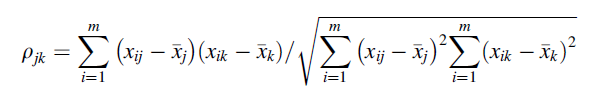

corr = sum((normIPF-meannormIPF).*(normSEA-meannormSEA)/(sqrt(sum((normIPF-meannormIPF).^2).*sum(normSEA-meannormSEA).^2)));

Determine standard deviation.

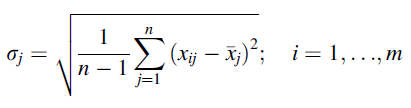

sdIPF = sqrt(sum(normIPF-meannormIPF).^2)./(n(1)-1);
sdSEA = sqrt(sum(normSEA-meannormSEA).^2)./(n(1)-1);

Determine index for each attribute.

indIPF = sdIPF.*(1-corr);
indSEA = sdSEA.*(1-corr);

Weights are obtained by

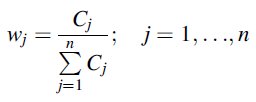

weightIPF = indIPF/(indIPF+indSEA);
weightSEA = indSEA/(indIPF+indSEA);